# TPA 3 MPC Grupo 10

A contiunación se obtiene el modelo discrete en espacio de estados a partir del modelo de orden 6 obtenido en el TP1 (identificación)

close all; clc;
s = tf('s');

% addpath(genpath('...'));
% savepath

% modelo de orden 6
model_6 = 1.261e06/(s^6 + 75.11* s^5 + 1869* s^4 + 2.523e04* s^3 + 1.888e05* s^2 + 7.568e05* s + 1.26e06)


model_6 =
 
                                  1.261e06
  ------------------------------------------------------------------------
  s^6 + 75.11 s^5 + 1869 s^4 + 25230 s^3 + 188800 s^2 + 756800 s + 1.26e06
 
Continuous-time transfer function.
Model Properties


% model_6 = 10/(s*s+0.1*s+3);

[p, z] = pzmap(model_6);
high_freq_pole = abs(max(p));

% TIEMPO DE MUESTREO
Ts = round(1/(5*high_freq_pole), 3)

Ts = 0.0050


model_discrete = c2d(model_6, Ts)


model_discrete =
 
  2.594e-11 z^5 + 1.402e-09 z^4 + 7.044e-09 z^3 + 6.676e-09 z^2 + 1.194e-09 z + 1.984e-11
  ---------------------------------------------------------------------------------------
          z^6 - 5.647 z^5 + 13.28 z^4 - 16.64 z^3 + 11.72 z^2 - 4.397 z + 0.6869
 
Sample time: 0.005 seconds
Discrete-time transfer function.


[model_A, model_B, model_C, model_D] = tf2ss(model_discrete.Numerator{1}, model_discrete.Denominator{1});

Se verifican los modelos continuos y discretos comparando sus respuestas al escalón

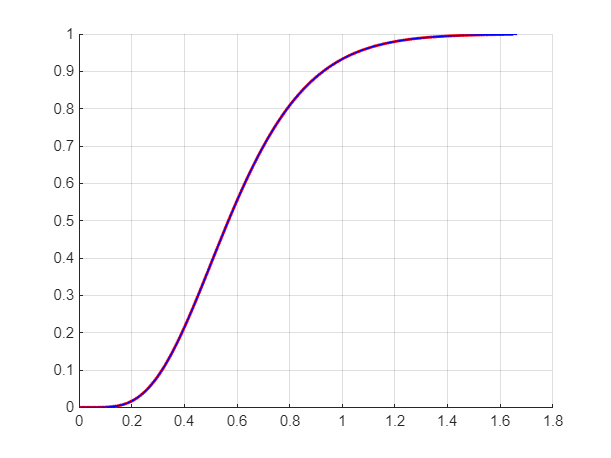

[cont_y, cont_t] = step(model_6);
[disc_y, disc_t] = step(model_discrete);

figure; hold on; grid on;
plot(cont_t, cont_y, 'r', 'LineWidth', 2);
plot(disc_t, disc_y, 'b', 'LineWidth', 1);

Ahora se obtiene el modelo en espacio de estados pero considerando variaciones en la entrada en de las muestras $\Delta U$(modelo incremental = inc_model)

A_expanded = [model_A, model_B; zeros(1, length(model_A)), ones(1, 1)];
B_expanded = [model_B; ones(1, 1)];
C_expanded = [model_C, zeros(1,1)];

inc_model = ss(A_expanded, B_expanded, C_expanded, 0, Ts)


inc_model =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7
   x1    5.647   -13.28    16.64   -11.72    4.397  -0.6869        1
   x2        1        0        0        0        0        0        0
   x3        0        1        0        0        0        0        0
   x4        0        0        1        0        0        0        0
   x5        0        0        0        1        0        0        0
   x6        0        0        0        0        1        0        0
   x7        0        0        0        0        0        0        1
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
   x5   0
   x6   0
   x7   1
 
  C = 
              x1         x2         x3         x4         x5         x6         x7
   y1  2.594e-11  1.402e-09  7.044e-09  6.676e-09  1.194e-09  1.984e-11          0
 
  D = 
       u1
   y1   0
 
Sample time: 0.005 seconds
Discrete-time state-space model.


Se cargan las matrices F y $\phi \;$

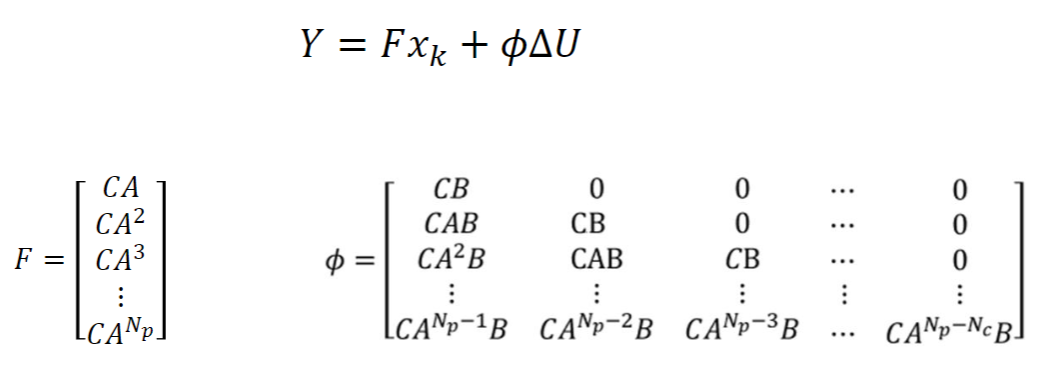

## Para calcular Np consideré que si Ts=0.1 y Tr=1.4 entonces entran 14 muestras hasta que se extinguen los transitorios

# IMPORTANTE: No se si lo anterior es cierto

% Np = round(1.4/Ts);
% Nc = 3;

% Esto genera F para un rango dinámico Np
% F_mat = zeros(Np, length(A_expanded));
% F_mat(1, :) = C_expanded*A_expanded;
% for i = 2:Np
%     F_mat(i, :) = F_mat(i-1, :)*A_expanded;
% end
% F_mat
% 
% % Esto genera phi para un rango dinámico de Np y Nc
% phi_mat = zeros(Np, Nc);
% for j = 1:Nc
%     for i = 1:Np
%         if (i < j)
%             phi_mat(i, j) = 0;
%         elseif (i == j)
%             phi_mat(i, j) = C_expanded*B_expanded;
%         else
%             phi_mat(i, j) = C_expanded*(A_expanded^(Np-j))*B_expanded;
%         end
%     end
% end
% phi_mat

% reference = 1;
% [Phi_Phi,Phi_F,Phi_R,A_e, B_e,C_e] = mpcgain(A_expanded, B_expanded, C_expanded, Nc, Np, reference);

A continuación se calculan las entradas $\Delta U$de manera analítica

% states = zeros(length(A_expanded), 1);
% ref_weight_mat = 0.1*eye(Nc);
% Rs = ones(1, Np);
% dU = ((((phi_mat')*phi_mat+ref_weight_mat)^(-1))*(phi_mat'))*(Rs*reference-F_mat*states)

% Rs*reference
% F_mat*states
% (Rs*reference-F_mat*states)

% states = zeros(length(A_expanded), 1);
% ref_weight_mat = 0.1*eye(Nc);
% dU = ((Phi_Phi + ref_weight_mat)^(-1)) * ( Phi_R - Phi_F *  states)

Ahora se hace una simulación de la acción de control en diferencias

Np = round(1.4/Ts);
Nc = 3;
reference = 1;
ref_weight_mat = 0.1*eye(Nc);
[Phi_Phi,Phi_F,Phi_R,A_e, B_e,C_e] = mpcgain(A_expanded, B_expanded, C_expanded, Nc, Np, reference);

BarRs =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


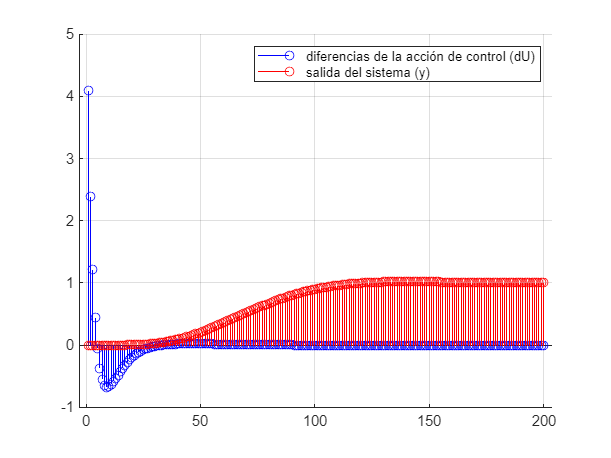


sim_length = 200;
x = zeros(1, sim_length);
y = zeros(1, sim_length);

for i = 1:sim_length
    dU = ((Phi_Phi + ref_weight_mat)^(-1)) * ( Phi_R - Phi_F *  states);
    x(i) = dU(1);
    states = A_expanded*states + B_expanded*x(i); 
    y(i) = C_expanded*states;
end

fig = figure();
hold on; grid on;

stem(x, 'b');
stem(y, 'r');

legend('diferencias de la acción de control (dU)', 'salida del sistema (y)');

Ahora si quiero aplicar restricciones a la acción de control por ejemplo, no podría resolverlo de manera analítica, necesitaria usar un solver, por ejemplo empleo uno de la librería yamilp:

% Modelo
% numG = [10];
% denG = [1 0.1 3];
% [Ac, Bc, Cc, Dc] = tf2ss(numG, denG);
% plantac = ss(Ac, Bc, Cc, Dc);

% Planta discreta
% ts = 0.01;
% plantad = c2d(plantac, ts);
% Am = plantad.A;
% Bm = plantad.B;
% Cm = plantad.C;
% Dm = plantad.D;
Am = model_A;
Bm = model_B;
Cm = model_C;
Dm = model_D;

% Modelo incremental
% A = [Am [0 0]'; Cm*Am 1];
% B = [Bm; Cm*Bm];
% C = [[0 0] 1];
% D = 0;
A = A_expanded;
B = B_expanded;
C = C_expanded;
D = 0;
nx = length(A); % Número de estados
nu = 1; % Número de entradas
ny = 1; % Número de salidas

% Datos MPC
% Np = 20;
% Nc = 3;
rw = 0.01;
R = rw.*eye(nu);

% Variables
u = sdpvar(Nc, nu);
uant = sdpvar(1, 1);
x = sdpvar(nx, Np+1);
r = sdpvar(Np, ny);

% Inicialización
constraints = [];
objective = 0;

for k = 1:Nc
    constraints = [constraints, x(:,k+1) == A*x(:,k) + B*u(k)];
    constraints = [constraints, -3 <= uant+sum(u(1:k)) <= 6];
    objective = objective + (r(k)-C*x(:,k+1))'*(r(k)-C*x(:,k+1)) + u(k)'*R*u(k);
end

for k = Nc+1:Np
    constraints = [constraints, x(:,k+1) == A*x(:,k)];
    objective = objective + (r(k)-C*x(:,k+1))'*(r(k)-C*x(:,k+1));
end

ops = sdpsettings('verbose', 2);
controller = optimizer(constraints, objective, ops, {x(:,1), uant, r(:)}, u(:));

% Simulación
xm = zeros(length(Cm), 1);
ym = Cm*xm;
u = 0;
dui = 0;
sim_i = 1;
sim_f = 61;
xf = zeros(nx, 1);
ref = [ones(Np, 1)];
usup = 6;
uinf = -3;
ua = 0;

for ii = sim_i:sim_f
    deltaU = controller(xf, u, ref);
    deltaUs(ii,:) = deltaU;
    dua = deltaU(1);
    dui(ii) = dua;
    u = u + dua;
    ua = u;
    if (ua > usup)
        ua = usup;
    end
    if (ua < uinf)
        ua = uinf;
    end
    us(ii) = ua;
    ys(ii) = ym;
    xs(:,ii) = xm;
    xant = xm;
    xm = Am*xm + Bm*ua;
    ym = Cm*xm;
    xf = [xm-xant; ym];
end


The problem is non-convex.



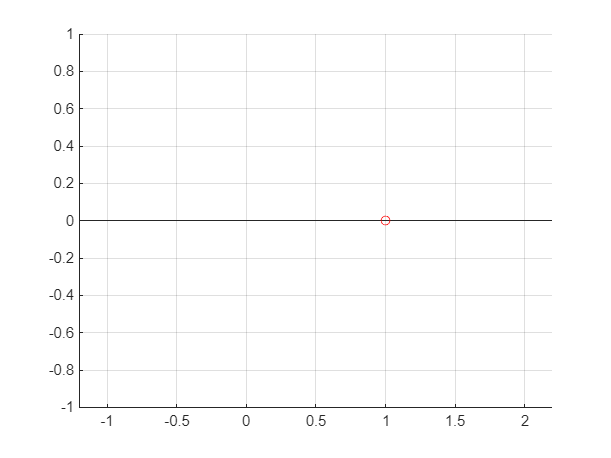


fig = figure();
hold on; grid on;

stem(ys, 'r');
stem(us, 'b');